# Arbitrary Array Beamforming

This notebook presents the implementation of various array beamforming techniques and analyzes performance degradation due to mutual coupling and noise. The simulation models a configurable array with user-defined parameters, utilizing a Log-Periodic Dipole Antenna (LPDA) at each node.

#### **Simulation Parameters**

To begin, the fundamental parameters for the simulation are defined, including the center frequency, number of elements in the array, and the inter-element spacing. These parameters define the spatial resolution and geometry for the subsequent beamforming and pattern analysis.

clc; clear;

c = physconst('LightSpeed');           % Speed of light [m/s]
fc = 25e6;                             % Center frequency [Hz]
lambda = c / fc;                       % Wavelength [m]
kc = 2*pi/lambda;                      % Wave number [rad/m]

nElem = 16;                            % Number of antenna elements
dElem = 0.55 * lambda;                 % Inter-element spacing [m]

K = 1000;                              % Number of angular samples (fidelity)
azAngles = linspace(-pi/2, pi/2, K).'; % Azimuth scan angles [rad]
elAngles = linspace(-pi/2, pi/2, K).'; % Elevation scan angles [rad]

#### Construct LPDA Element Geometry

An LPDA (Log-Periodic Dipole Antenna) is constructed based on the wavelength corresponding to the defined center frequency. The LPDA is chosen for its broadband performance and directional gain.

% Define LPDA element structure
element = lpda;
element.BoardLength = 0.75 * lambda;
element.BoardWidth  = 0.75 * lambda;
element.Height      = 0.01 * lambda;
element.StripLineWidth = 0.005 * lambda;
element.FeedLength     = 0.025 * lambda;

% Define LPDA arm configuration
nArms = 8;
armStart = 0.16 * lambda;
armEnd   = 0.34 * lambda;
element.ArmLength  = linspace(armStart, armEnd, nArms);
element.ArmWidth   = 0.02 * element.ArmLength;
element.ArmSpacing = linspace(0.08, 0.12, nArms-1) * lambda;

% Orient the LPDA element by tilting along the y-axis
element.TiltAxis = [0 1 0; 1 1 0];
element.Tilt     = [180 180];

% Visualize the single antenna element
figure("Name", "Single Element Geometry");
show(element);
title("LPDA Antenna Configured for 25 MHz");
axis equal;
grid on;
view(0, 270);

Further electromagnetic characterization of the LPDA element includes impedance matching and bandwidth performance, which can be analyzed using MATLAB’s Antenna Toolbox. These plots provide insight into the antenna's operational frequency range and impedance characteristics, which are critical for effective matching and array design.

% % Define frequency sweep range for analysis (±10% around fc)
% freqSweep = linspace(fc - (0.1 * fc), fc + (0.1 * fc), 10);
% 
% % Plot input impedance of the element
% figure("Name", "Single Element Impedance Sweep");
% impedance(element, freqSweep);
% 
% % Estimate absolute bandwidth over the frequency range
% figure("Name", "Single Element Bandwidth");
% absBW = bandwidth(element, freqSweep);

#### **Compute Element Radiation Pattern**

The directional gain characteristics of a single LPDA element are evaluated using MATLAB's `pattern` function, which simulates the radiated fields based on current distributions over the antenna geometry. The element gain is computed over a range of azimuth and elevation angles at the center frequency.

% Compute element pattern in azimuth and elevation cuts
elementPatternAz = 10.^(pattern(element, fc, rad2deg(azAngles - pi/2), 0, 'Type', 'gain') / 10).';
elementPatternEl = 10.^(pattern(element, fc, 0, rad2deg(azAngles - pi/2), 'Type', 'gain') / 10).';

% Optionally save and load precomputed data to save simulation time
save('patterns/elementPatternAz.mat', 'elementPatternAz');
save('patterns/elementPatternEl.mat', 'elementPatternEl');
load('patterns/elementPatternAz.mat');
load('patterns/elementPatternEl.mat');

% Normalize the element patterns to their respective maxima
elementPatternAz = elementPatternAz / max(elementPatternAz);
elementPatternEl = elementPatternEl / max(elementPatternEl);

The normalized azimuth and elevation gain patterns are plotted in decibels to visualize the directional response of the antenna element. These plots show the normalized radiation pattern of a single LPDA element in both the azimuth and elevation planes, allowing us to evaluate its directivity and beam symmetry. These patterns serve as the fundamental building blocks for forming the overall array response in subsequent beamforming stages.

% Plot normalized element patterns in azimuth and elevation
figure("Name", "Single Element Azimuth and Elevation Patterns", "Color", "w");
subplot(2, 1, 1);
plot(rad2deg(azAngles), 10*log10(elementPatternAz.^2), 'Color', [0.6350, 0.0780, 0.1840], 'LineWidth', 2.0);
xlabel('Azimuth Angle (deg)');
ylabel('Gain (dB)');
title('Element Azimuth Pattern');
grid on;
xlim([-90 90]);
subplot(2, 1, 2);
plot(rad2deg(azAngles), 10*log10(elementPatternEl.^2), 'Color', [0.0000, 0.4470, 0.7410], 'LineWidth', 2.0);
xlabel('Elevation Angle (deg)');
ylabel('Gain (dB)');
title('Element Elevation Pattern');
grid on;
xlim([-90 90]);
sgtitle('Single Element Radiation Patterns (Normalized Gain)');
set(gcf, 'Position', [100, 100, 700, 600]);

#### **Construct Array Geometry**

The antenna array is constructed as a **linear, uniformly spaced conformal array** of LPDA elements, aligned along the **x-axis**. The spatial coordinates of each element are calculated relative to the array's geometric center. The `conformalArray` object allows for arbitrary 3D element positioning and orientation. In this case, all elements share identical orientation and reside in the same plane.

% Define array cartesian coordinates
elementXPositions = dElem * ((0: nElem-1) - (nElem-1)/2).';
elementYPositions = zeros(nElem, 1);
elementZPositions = zeros(nElem, 1);

% Generate confromal array geometry
array = conformalArray;
array.Element = element;
array.ElementPosition = [elementXPositions, elementYPositions, elementZPositions];

% Plot 3-dimensional array geometry
figure("Name", "Array Geometry");
show(array);

#### Compute Array Factor

The array factor (AF) quantifies the directional response due solely to the spatial configuration and phase weighting of the array elements, excluding the element radiation pattern. This section computes the AF for azimuth and elevation cuts as well as the full 3D pattern.

% Define steering angles (radians)
azSteer = deg2rad(0);
elSteer = deg2rad(0);

% Convert to a 3D direction unit vector
u = [sin(azSteer)*cos(elSteer), cos(azSteer)*cos(elSteer), sin(elSteer)].';

% Compute array steering vector for desired direction
svSteer = exp(-1j * kc * (array.ElementPosition * u));
svSteer = svSteer / norm(svSteer);

% Define spatial directions and response matrix across azimuth sweep
UFixedEl = [sin(azAngles).*cos(zeros(K, 1)), cos(azAngles).*cos(zeros(K, 1)), sin(zeros(K, 1))].';
S = exp(-1j * kc * (array.ElementPosition * UFixedEl));

% Compute and normalize the array factor
arrayFactorAz = S' * svSteer;
arrayFactorAz = arrayFactorAz / max(arrayFactorAz);
arrayFactorAzdB = 20 * log10(abs(arrayFactorAz));

% Define spatial directions and response matrix across elevation sweep
UFixedAz = [sin(zeros(K, 1)).*cos(elAngles), cos(zeros(K, 1)).*cos(elAngles), sin(elAngles)].';
S = exp(-1j * kc * (array.ElementPosition * UFixedAz));

% Compute and normalize the array factor
arrayFactorEl = S' * svSteer;
arrayFactorEl = arrayFactorEl / max(arrayFactorEl);
arrayFactorEldB = 20 * log10(abs(arrayFactorEl));

Plot the corresponding azimuth and elevation Array Factor cuts as well as full 3D azimuth elevation heatmap.

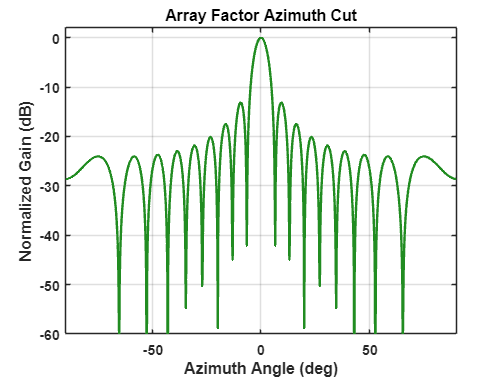

% Plot 2D array factor across azimuth sweep
figure("Name", "Array Factor - Azimuth Sweep", "Color", "w");
plot(rad2deg(azAngles), arrayFactorAzdB, 'Color', [0.13, 0.55, 0.13], 'LineWidth', 2.0);
xlabel('Azimuth Angle (deg)');
ylabel('Normalized Gain (dB)');
title('Array Factor Azimuth Cut');
grid on;
xlim([-90 90]);
ylim(max(arrayFactorAzdB) + [-60 2]);
set(gca, 'FontSize', 12, 'FontWeight', 'bold');

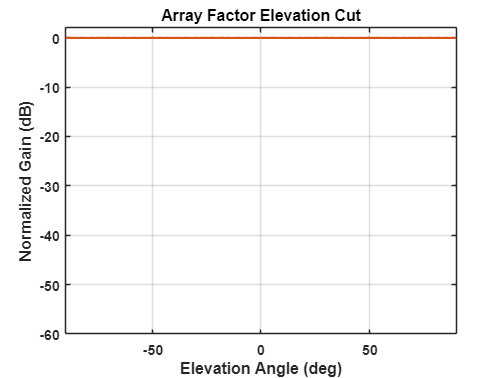


% Plot 2D array factor across elevation sweep
figure("Name", "Array Factor - Elevation Sweep", "Color", "w");
plot(rad2deg(elAngles), 20*log10(abs(arrayFactorEl)), 'Color', [0.85, 0.33, 0.10], 'LineWidth', 2.0);
xlabel('Elevation Angle (deg)');
ylabel('Normalized Gain (dB)');
title('Array Factor Elevation Cut');
grid on;
xlim([-90 90]);
ylim(max(arrayFactorEldB) + [-60 2]);
set(gca, 'FontSize', 12, 'FontWeight', 'bold');

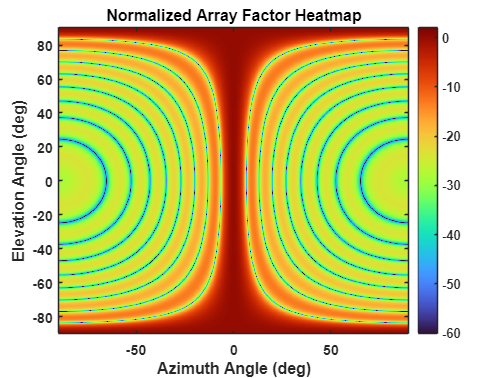


% Compute array factor over azimuth and elevation
[AZ, EL] = meshgrid(azAngles, elAngles);
Ux = sin(AZ) .* cos(EL);
Uy = cos(AZ) .* cos(EL);
Uz = sin(EL);
U = [Ux(:) Uy(:) Uz(:)].';
S = exp(-1j * kc * (array.ElementPosition * U));
AF = svSteer' * S;
AF = reshape(AF, K, K);
AF_dB = 20*log10(abs(AF) / max(abs(AF(:))));

% Plot 3D array factor across both azimuth and elevation
figure("Name", "3D Array Factor", "Color", "w");
imagesc(rad2deg(azAngles), rad2deg(elAngles), AF_dB);
set(gca, 'YDir', 'normal');
xlabel('Azimuth Angle (deg)');
ylabel('Elevation Angle (deg)');
title('Normalized Array Factor Heatmap');
colorbar;
colormap(turbo);
clim(max(AF_dB(:)) + [-60 2]);
set(gca, 'FontSize', 12, 'FontWeight', 'bold');

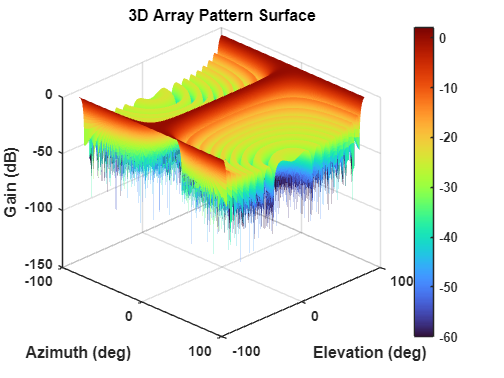


% plot 3D array pattern as mesh surface
figure("Name", "Normalized Array Factor Mesh", "Color", "w");
surf(rad2deg(AZ), rad2deg(EL), AF_dB, 'EdgeColor', 'none');
xlabel('Azimuth (deg)');
ylabel('Elevation (deg)');
zlabel('Gain (dB)');
title('3D Array Pattern Surface');
colormap(turbo);
colorbar;
clim(max(AF_dB(:)) + [-60 2]);
view(45, 30);
grid on;
set(gca, 'FontSize', 12, 'FontWeight', 'bold');

#### **Compute Full Array Radiation Pattern**

The full array radiation pattern is computed by applying the pattern multiplication principle, which combines the element radiation pattern with the array factor. This provides an accurate representation of the total far-field response of the array. The azimuth and elevation cuts are obtained by multiplying the respective element pattern with the corresponding array factor.

% Compute full array pattern by combining element pattern and array factor
arrayPatternAz = elementPatternAz .* arrayFactorAz;

Unrecognized function or variable 'elementPatternAz'.

arrayPatternEl = elementPatternEl .* arrayFactorEl;

% Normalize to peak value
arrayPatternAz = arrayPatternAz / max(abs(arrayPatternAz));
arrayPatternEl = arrayPatternEl / max(abs(arrayPatternEl));

% Convert to dB scaling
arrayPatternAzdB = 20*log10(abs(arrayPatternAz));
arrayPatternEldB = 20*log10(abs(arrayPatternEl));

The 2D plots below show how the LPDA element's directivity influences the array’s overall performance. The array factor shapes the main lobe and side lobes, while the element pattern dictates the effective beamwidth and angular attenuation.

% Azimuth Cut (Elevation = 0)
figure("Name", "Array Pattern - Azimuth Sweep", "Color", "w");
plot(rad2deg(azAngles), arrayPatternAzdB, 'Color', [0.13, 0.55, 0.13], 'LineWidth', 2.0);
xlabel('Azimuth Angle (deg)');
ylabel('Normalized Gain (dB)');
title('Total Array Pattern vs. Azimuth');
grid on;
xlim([-90 90]);
ylim(max(arrayPatternAzdB) + [-60 2]);
set(gca, 'FontSize', 12);

% Elevation Cut (Azimuth = 0)
figure("Name", "Array Pattern - Elevation Sweep", "Color", "w");
plot(rad2deg(elAngles), arrayPatternEldB, 'Color', [0.85, 0.33, 0.10], 'LineWidth', 2.0);
xlabel('Elevation Angle (deg)');
ylabel('Normalized Gain (dB)');
title('Total Array Pattern vs. Elevation');
grid on;
xlim([-90 90]);
ylim(max(arrayPatternEldB) + [-60 2]);
set(gca, 'FontSize', 12);

To evaluate the array's behavior across the full spherical field, we compute the **3D radiation pattern** over both azimuth and elevation.

% Define full 3D direction vectors over angular grid
[AZ, EL] = meshgrid(azAngles, elAngles);
Ux = sin(AZ) .* cos(EL);
Uy = cos(AZ) .* cos(EL);
Uz = sin(EL);
U = [Ux(:)'; Uy(:)'; Uz(:)'];

% Compute array factor over 3D space
S = exp(-1j * kc * (array.ElementPosition * U));
AF = svSteer' * S;
AF = reshape(AF, K, K);

% Construct 2D element pattern via outer product
EP = elementPatternAz(:) .* elementPatternEl(:).';

% Compute total array radiation pattern
AP = AF .* EP;
AP_dB = 20 * log10(abs(AP) / max(abs(AP(:))));

% plot 3D array pattern as heat map
figure("Name", "3D Array Pattern Heatmap", "Color", "w");
imagesc(rad2deg(azAngles), rad2deg(elAngles), AP_dB);
set(gca, 'YDir', 'normal');
xlabel('Azimuth Angle (deg)');
ylabel('Elevation Angle (deg)');
title('3D Array Pattern (Azimuth vs Elevation)');
colorbar;
colormap(turbo);
clim(max(AP_dB(:)) + [-60 2]);
set(gca, 'FontSize', 12);

% plot 3D array pattern as mesh surface
figure("Name", "3D Array Pattern Mesh", "Color", "w");
surf(rad2deg(AZ), rad2deg(EL), AP_dB, 'EdgeColor', 'none');
xlabel('Azimuth (deg)');
ylabel('Elevation (deg)');
zlabel('Gain (dB)');
title('3D Array Pattern Surface');
colormap(turbo);
colorbar;
clim(max(AP_dB(:)) + [-60 2]);
view(45, 30);
grid on;
set(gca, 'FontSize', 12);